# Modelling common 1st order systems

Modelling is generally achieved using a balance equation (e.g force, voltage, pressure, flow, etc.) alongside component equations. Of interest here is how these models are expressed within MATLAB.

Three common model types are illustrated: 

- ODE (differential equation).   [Use symbolic variables]

- Transfer function (Laplace).   [Use tf.m]

- State space.                           [Use ss.m]

Assume that a first order model can be represented by a differential equation or transfer function or state space model as follows:

$T\frac{\textrm{dx}}{\textrm{dt}}+x=C\;u;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;G\left(s\right)=\frac{C}{\textrm{Ts}+1}$;                          $\overset{\ldotp }{x} =\textrm{Ax}+\textrm{Bu}$

You must have the symbolic toolbox installed for this file to work.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Deriving ODE models from a balance equation

- Storing in MATLAB as an ODE model

- Storing as a transfer function

- Storing as a state-space model

## 1. Deriving ODE models from a balance equation

*For simplicty below, we do not engage with details linked to deviation variables and non-zero steady-states.*

For a mass-damper we use force balance across the mass and damper.


$$\textrm{f1}=M\frac{\textrm{dv}}{\textrm{dt}};\;\;\;\;\textrm{f2}=B\;v;\;\;\;\;f=\textrm{f1}+\textrm{f2}\;\Longrightarrow \;f=M\frac{\textrm{dv}}{\textrm{dt}}+B\;v\;$$


For a spring damper we use force balance across the spring and damper.


$$\textrm{f1}=B\frac{\textrm{dx}}{\textrm{dt}};\;\;\;\;\textrm{f2}=\textrm{kx};\;\;\;\;f=\textrm{f1}+\textrm{f2}\;\Longrightarrow \;f=B\frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}\;$$


For a series resistor-capacitor circuit damper we use voltage balance across the components.


$$\textrm{v1}=R\frac{\textrm{dq}}{\textrm{dt}};\;\;\;\;\textrm{v2}=\frac{q}{C};\;\;\;\;v=\textrm{v1}+\textrm{v2}\;\Longrightarrow \;v=R\frac{\textrm{dq}}{\textrm{dt}}+\frac{q}{C}\;$$


For a series resistor-inductor circuit damper we use voltage balance across the components.


$$\textrm{v1}=L\frac{\textrm{di}}{\textrm{dt}};\;\;\;\;\textrm{v2}=\textrm{iR};\;\;\;\;v=\textrm{v1}+\textrm{v2}\;\Longrightarrow \;v=L\frac{\textrm{di}}{\textrm{dt}}+\textrm{iR}$$


For a tank with outflow proportional to depth and an in-flow we use pressure  across the outlet to determine the flow out and a volume/flow balance.


$$\textrm{P1}=\rho \textrm{gh}=Rf_{\textrm{out};\;\;\;\;\;\;\;\;\;} \frac{\textrm{dV}}{\textrm{dt}}=f_{\textrm{in}} -f_{\textrm{out}} =A\frac{\textrm{dh}}{\textrm{dt}}\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;f_{\textrm{in}} =A\frac{\textrm{dh}}{\textrm{dt}}+\frac{\rho \textrm{gh}}{R}$$


For a thermal system we use heat flow/energy balance assuming heat loss (watts) is proportional to temperature and heat stored is also proportional to temperature.


$$P_{\textrm{loss}} =\textrm{kT};\;\;\;\;\;\;\frac{d}{\textrm{dt}}\left(E_{\textrm{store}} \right)=C\frac{\textrm{dT}}{\textrm{dt}}$$

$$\;\;\Longrightarrow \;\;\;\;\;\;W=C\frac{\textrm{dT}}{\textrm{dt}}+\textrm{kT}$$


## 2. Storing in MATLAB as an ODE model

Generate symbolic variables for the model state and the derivative.

For a mass-damper with state v: $\;f=M\frac{\textrm{dv}}{\textrm{dt}}+B\;v\;$

syms v(t)
Dv=diff(v);        %% symbolic expression for dv/dt
M=10; B=1; f=2;    %% indicate values
model = f==M*Dv+B*v

$$model(t) = 2=10\,\frac{\partial }{\partial t}v\left(t\right)+v\left(t\right)$$

v = dsolve(model,v(0)==0)    %%% Finds a generic solution

$$v = 2-2\,{\mathrm{e}}^{-\frac{t}{10}}$$

For a series resistor-inductor circuit with state i$:\;\;v=L\frac{\textrm{di}}{\textrm{dt}}+\textrm{iR}$

syms i(t)
Di=diff(i);        %% symbolic expression for di/dt
R=0.1; L=0.02; v=3.4;    %% indicate values
model2 = v==L*Di+R*i

$$model2(t) = \frac{17}{5}=\frac{\frac{\partial }{\partial t}i\left(t\right)}{50}+\frac{i\left(t\right)}{10}$$

i = dsolve(model2,i(0)==0)    %%% Finds 

$$i = 34-34\,{\mathrm{e}}^{-5\,t}$$

## 3. Storing as a transfer function

First recognise how a generic ODE is expressed as a transfer function. MATLAB then use the numerator and denomnator coefficients.


$$F\frac{\textrm{dx}}{\textrm{dt}}+\textrm{Bx}\;=\;\textrm{Du}\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;\;\;\;\;\left\lbrack \textrm{Fs}+B\right\rbrack X\left(s\right)=\textrm{DU}\left(s\right)\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;\;\;X\left(s\right)=\frac{D}{\textrm{Fs}+B}U\left(s\right)$$


Hence here the model is:  

D=1; B=2; F=2.4;
G = tf(D,[F,B])

G =
 
      1
  ---------
  2.4 s + 2
 
Continuous-time transfer function.



For a thermal system $\;\;\;W=C\frac{\textrm{dT}}{\textrm{dt}}+\textrm{kT}$   so $D=1,F=C,B=k$

C=10000;  k=250;
thermal  =tf(1,[C,k])

thermal =
 
        1
  -------------
  10000 s + 250
 
Continuous-time transfer function.



For a tank model $\;\;\;\;\;\;\;f_{\textrm{in}} =A\frac{\textrm{dh}}{\textrm{dt}}+\frac{\rho \textrm{gh}}{R}$  then $D=1,F=A,B=\frac{\rho g}{R}$

A=10; rho=1000;g=9.8; R=10000;
tank = tf(1,[A,rho*g/R])

tank =
 
       1
  -----------
  10 s + 0.98
 
Continuous-time transfer function.



The numerical (not analytical) response from a transfer function model can be determined using functions such as ***step.m*** and ***impulse.m***, for example.  [More details of these functions elsewhere]

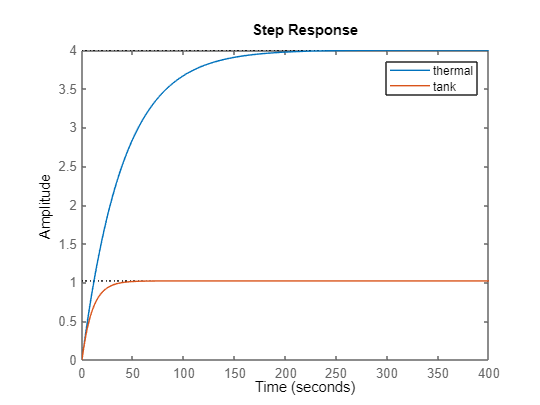

step(thermal*1000,tank); 
legend('thermal','tank')

## 4: Storing as a state-space model

First recognise how a generic ODE is expressed as a state space model by re-arranging and setting the coefficient of the derivative to be one. The state-space model is expressed in generic form as:


$$\frac{\textrm{dx}}{\textrm{dt}}=\textrm{Ax}+\textrm{Bu};\;\;y=\textrm{Cx}+\textrm{Du}\;;\;\;\;\;$$


For simplicity here assume the output is the state so *C=1 and D=0*.

The state-space model is created using  G = ss(A,B,C,D)

A series resistor-capacitor circuit $\;v=R\frac{\textrm{dq}}{\textrm{dt}}+\frac{q}{C}\;$is rearranged to 

$\frac{\textrm{dq}}{\textrm{dt}}=-\frac{q}{\textrm{CR}}+\frac{1}{R}v$  so* A=-1/(CR), B=1/R, C=1, D=0*

R=1; C=2;
RCmodel = ss(-1/(C*R),1/R,1,0)

RCmodel =
 
  A = 
         x1
   x1  -0.5
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



For a spring damper $\;f=B\frac{\textrm{dx}}{\textrm{dt}}+\textrm{kx}\;$is changed to $\frac{\textrm{dx}}{\textrm{dt}}=-\frac{k}{B}x+\frac{1}{B}f$

B=200; k=50;
springdamp_model = ss(-k/B,1/B,1,0)

springdamp_model =
 
  A = 
          x1
   x1  -0.25
 
  B = 
          u1
   x1  0.005
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



The numerical (not analytical) response from a state-space model can be determined using functions such as ***step.m*** and ***impulse.m***, for example.  [More details of these functions elsewhere]

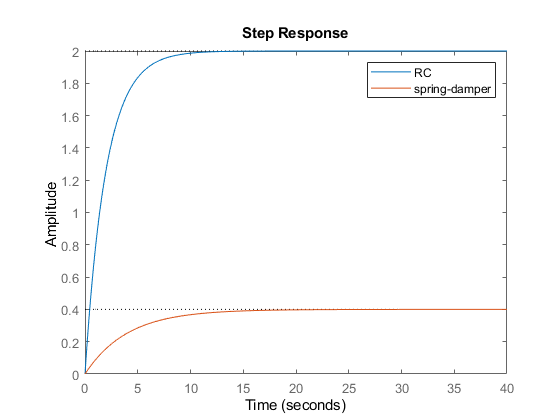

step(RCmodel,springdamp_model*20); 
legend('RC','spring-damper')